# 4C: Microstruttura in segnali EEG

### Lorenzo Gerini, Lavinia Scimone

## Introduzione

L’elettroencefalografia (EEG) è un metodo molto utile per studiare l’elettrofisiologia del cervello in uno stato di riposo con alta risoluzione temporale. In particolare, permette di caratterizzare l’attività spontanea cerebrale che non è rilevata quando un soggetto svolge attività cognitive.

Il termine EEG è stato coniato da Hans Berger, il quale descrisse delle specifiche onde cerebrali, oggi chiamate oscillazioni alpha (8-12 Hz), rilevate nella zona occipitale in un paziente in stato di riposo ad occhi chiusi (Berger, 1929). Da quel momento numerosi studi hanno associato varie bande di frequenze corticali con diverse malattie e disturbi comportamentali. Lo studio si è evoluto definendo stati momentanei e descrivendo cambiamenti nell’attività cerebrale attraverso la modifica di parametri temporali. 

Sono stati proposti diversi approcci analitici per estrarre informazioni dal segnale EEG, uno di questi, chiamato *Microstate Analysis*, considera l’EEG multicanale come una serie di microstati semi-stabili ognuno dei quali è caratterizzato da un’unica topografia di potenziali elettrici rispetto i canali. 

I principi di questo metodo sono stati descritti da Lehmann e i suoi collaboratori (Lehmann et al., 1987), i quali hanno osservato che una specifica configurazione di una mappa globale del cranio rimane stabile per un intervallo di tempo dell’ordine dei millisecondi per poi evolversi in un nuovo stato appartenente a un numero limitato di mappe dominanti semi-stabili. Il concetto di cluster è stato introdotto nell’analisi dei microstati da Pascual-Marqui et al. (1995), dove è stata considerata l’intera topografia, invece di usare solo la posizione dei potenziali massimi e minimi. Una teoria suggerisce che i microstati rappresentano operazioni mentali discrete che combinano per mettere in rialzo attività mentale spontanea. Per questo motivo i microstati vengono considerati "atomi di pensiero".

L’obiettivo di questo studio è quello di identificare i microstati di un segnale EEG a 64 canali di un soggetto a riposo e ad occhi chiusi e quindi studiarne la variazione nel tempo.   

## Materiali e Metodi

#### Acquisizione dei Dati

Sono stati utilizzati dati a riposo dal sito PhysioNet, a cui ha contribuito Schalk lab (Goldberger et al., 2000; Schalk et al., 2004) disponibile ad uso pubblico. Il database è costituito da 109 soggetti sottoposti ad attività motorie e di riposo. In questo particolare studio è stato selezionato il soggetto S092R02, dove R02 specifica che i segnali sono stati registrati in uno stato di riposo. I dati sono forniti in formato .edf. I 64 canali corrispondono a 64 elettrodi posizionati secondo lo standard internazionale 10-10 system, i cui segnali sono stati registrati usando il sistema BCI2000.  

#### Preprocessing 

In questo progetto non è stata applicata nessuna tecnica di filtraggio, in modo da mantenere la maggiore quantità possibile di informazione. Invece, nella letteratura scientifica vengono spesso applicati filtri passabanda (1-50 Hz) e si utilizza la Independent Component Analysis (ICA) per identificare ed eliminare eventuali artefatti, ad esempio il movimento delle palpebre (Jung et al., 2000; Makeig et al., 1996). 

#### Microstate Analysis

In generale, l’analisi dei microstati consiste nel trovare il set delle mappe spaziali più dominanti tra le diverse topografie del cranio nel dominio del tempo e, successivamente, l’associazione ad ogni istante del segnale EEG di queste *template maps*. Per trovare le mappe dominanti del soggetto preso in esame, per ogni istante di tempo, è stata calcolata la *global field power* (GFP), come nell’Equazione (1), dove K è il numero di elettrodi in ogni mappa, $V_{i}(t)$ è il potenziale rilevato nell’i-esimo elettrodo e $V_{mean}(t)$ è il potenziale medio di ogni elettrodo all’istante t.

$GFP={\sqrt {\frac{(\sum_{i}^K(V_{i}(t)-V_{mean}(t))^2)}{K}}}$         (1)

I picchi locali della curva GFP rappresentano momenti di alta sincronizzazione neuronale globale e le topografie del cranio attorno ad essi rimangono stabili, massimizzando il rapporto segnale rumore (Koening et al., 2002). Le mappe del cranio agli istanti di tempo corrispondenti a punti di massimo locale della GFP sono state processate attraverso degli algoritmi di clustering, in questo caso specifico il *k-means *e la* Gaussian Mixture*, per determinare le mappi più dominanti del soggetto. Entrambi necessitano a priori il numero di clusters.

Prima della stima effettiva di quest’ultimo, si effettua una *principal component analysis* (PCA). Abbiamo visualizzato la percentuale di varianza spiegata a seconda del numero di componenti principali attraverso i diagrammi di Pareto e di Lorenz. Inoltre, gli autovettori vengono graficati nello spazio delle prime tre componenti principali, questo ci permette di osservare quanto le variabili influenzano le componenti principali. 

In seguito, la scelta del numero di clusters è stata effettuata attraverso diversi metodi di valutazione a seconda dell’algoritmo di clustering preso in esame.

Per il *k-means* il primo criterio è quello di visualizzare il risultato dell’algoritmo di clustering nello spazio delle dimensioni ridotte supponendo un determinato numero di clusters. Il secondo calcola la media delle distanze di ogni data point dal centro del cluster a cui appartiene al variare di k e si osserva come questa quantità si comporta. E come ulteriore metodo di verifica per entrambi gli algoritmi di clustering presi in esame in questo studio, si è utilizzato il *silhouette criteria, *un metodo euristico di interpretazione e validazione della consistenza tra i clusters dei dati. La tecnica fornisce un’interpretazione grafica di quanto è ben classificato ogni oggetto. Il coefficiente di silhouette è una misura di quanto è simile un oggetto al suo stesso cluster rispetto agli altri. Questo valore varia tra -1 e +1, dove un valore elevato indica che l’oggetto è ben accoppiato al proprio cluster e male con quelli vicini. Se la maggior parte degli oggetti hanno un valore elevato allora la configurazione di clustering è appropriata. Nel caso in cui molti punti hanno un valore basso o negativo, allora la configurazione potrebbe avere troppi oppure pochi clusters. Inoltre, questo valore viene calcolato tenendo riferimento della distanza Euclidea. In questo metodo, il valore di k viene scelto tenendo conto del valore più alto della media dei coefficienti di silhouette. Infine, inoltre a quest’ultimo, per la *Gaussian Mixture *è stata osservata la *-loglikelihood* per trovare la stima di k.

Una volta trovata la stima ottimale del numero di clusters, utilizziamo i risultati degli algoritmi di clustering per identificare i microstati. Tramite questi ultimi è stato possibile ridefinire il segnale EEG originale nel dominio del tempo come segue: ogni istante di tempo dei dati originali è stato associato ad un microstato, considerando la più alta correlazione tra la topografia del cranio in un determinato istante e quella di ogni microstato. 

#### Parametri temporali

Per ogni microstato sono stati calcolati tre parametri:

- Durata media di vita (Average Lifespan of Microstate): è stata calcolata come il tempo durante il quale ogni mappa originale è stata assegnata allo stesso microstato, il quale inizia e finisce nel punto medio tra l’ultima mappa originale del microstato precedente e la prima mappa originale del microstato successivo.

- Frequenza di apparizione (Frequency of Appearance): calcolata contando il numero di singole apparizioni di ogni microstato diviso il tempo totale.

- Frazione totale di tempo coperto (Fraction Total Covered Time): calcolata come il rapporto tra il tempo trascorso in ogni microstato e il tempo totale.

### Risultati

clearvars;
close all;

% Label dei 64 Canali
channels = {'FC5','FC3','FC1','FCZ','FC2','FC4','FC6','C5','C3','C1','CZ',...
    'C2' ,'C4' ,'C6' ,'CP5' ,'CP3' ,'CP1','CPZ','CP2','CP4','CP6','FP1','FPZ',...
    'FP2','AF7','AF3','AFZ' ,'AF4' ,'AF8','F7','F5','F3','F1','FZ' ,'F2','F4',...
    'F6','F8','FT7','FT8','T7','T8','T9','T10','TP7','TP8','P7' ,'P5',...
    'P3' ,'P1','PZ' ,'P2' ,'P4' ,'P6' ,'P8' ,'PO7','PO3','POZ','PO4','PO8',...
    'O1' ,'OZ' ,'O2','IZ'};  

% Color map rosso-blu
map = zeros(21,3);
map(21,:) = [1,0,0];
map(20,:) = [1,1/10,1/10];
map(19,:) = [1,2/10,2/10];
map(18,:) = [1,3/10,3/10];
map(17,:) = [1,4/10,4/10];
map(16,:) = [1,5/10,5/10];
map(15,:) = [1,6/10,6/10];
map(14,:) = [1,7/10,7/10];
map(13,:) = [1,8/10,8/10];
map(12,:) = [1,9/10,9/10];
map(11,:) = [1,1,1];
map(10,:) = [9/10,9/10,1];
map(9,:) = [8/10,8/10,1];
map(8,:) = [7/10,7/10,1];
map(7,:) = [6/10,6/10,1];
map(6,:) = [5/10,5/10,1];
map(5,:) = [4/10,4/10,1];
map(4,:) = [3/10,3/10,1];
map(3,:) = [2/10,2/10,1];
map(2,:) = [1/10,1/10,1];
map(1,:) = [0,0,1];

col = ['r','b','g','c','y'];

% Funzione necessaria per "head plot"
%addpath('plot_topography');

% Dati relativi al soggetto selezionato
[hdr, record] = edfread('S092R02.edf');

'edfread' requires Signal Processing Toolbox.

record = record(1:64,1:9632);

record_t = record'; 

Una volta importati i dati del soggetto selezionato (*S092R02.edf*), è stata calcolata la GFP e i relativi picchi, quindi è stato estratto il segnale originale in questi punti.  

V_mean = mean(record_t,2);   
GFP = zeros(1,9632);

for i = 1 : 9632
    GFP(i) = sqrt((sum((record_t(i,:)-V_mean(i)).^2))/64);
end

[pks, locs] = findpeaks(GFP);
eeg_at_peaks = record_t(locs,:);

gfp_plot(GFP, record_t);
title('Figura 1')

In questa porzione di codice si applica l'algoritmo della PCA e si calcolano gli autovettori e autovalori della covarianza del data set contenente soltanto gli istanti relativi ai picchi di GFP (*eeg_at_peaks*). Si determina la percentuale della varianza calcolata per ogni componente, sia per il diagramma di Pareto che per quello di Lorenz. 

% Principal Component Analysis
[U,X,S]=pca(zscore(eeg_at_peaks));

% Pareto
figure
bar(100*S./sum(S))
title('Figura 2')
xlabel('# components')
ylabel('variance explained [%]')
box off

% Lorenz
figure
plot(100*cumsum(S)./sum(S))
title('Figura 3')
xlabel('# components')
ylabel('variance explained [%]')
box off


Si utilizza l'algoritmo k-means per identificare se ci sono clusters nei dati. Si utilizzano i dati originali e non le loro proiezioni. Si visualizzano i dati nello spazio ridotto utilizzando differenti colori per i diversi cluster.

k = 4; 
idx = kmeans(eeg_at_peaks,k);  
cols = {'b','r','g','m','c'};
figure
for ii = 1:k
    is_ii = find(idx == ii);
    mu_ii = nanmean(X(is_ii,1:3));
    hold on
    plot3(X(is_ii,1),X(is_ii,2),X(is_ii,3),'.','MarkerFaceColor',cols{ii},'MarkerEdgeColor',cols{ii})
    plot3(mu_ii(1),mu_ii(2),mu_ii(3),'bo','MarkerSize',5,'MarkerFaceColor','k','MarkerEdgeColor','k')
    view(3)
    xlabel('PC_1')
    ylabel('PC_2')
    zlabel('PC_3')
end
title('Figura 4')

Per capire il numero corretto dei clusters, si fanno prove con diversi valori di k (da 1 a 8). Per ogni k si calcola la distanza media di ogni data point dal centro del cluster a cui appartiene.

k = 8;
figure
for ii = 1:k
    [idx,C,sumd] = kmeans(eeg_at_peaks,k);
    hold on
    scatter(ii,sum(sumd),'red','filled')
    xlabel('# clusters')
    ylabel('avg distance')
end
title('Figura 5')

Si utilizza la funzione di Matlab *evalclusters *per valutare il numero ottimale di clusters attraverso il *Silhouette Criteria. *Successivamente si rappresentano graficamente i coeffeicienti di Silhouette per ogni data point.

E1 = evalclusters(eeg_at_peaks, 'kmeans', 'silhouette','klist', 1:7);
figure 
plot(E1); 
title('Figura 6')
k = E1.OptimalK; 

[idx, C] = kmeans(eeg_at_peaks, k);
figure 
silhouette(eeg_at_peaks, idx);
title('Figura 7')

In questa sezione si effettua un' analisi con un algoritmo di clustering alternativo al k-means, *Gaussian Mixture*.

k = 4;
rng(1);
try
GMModel = fitgmdist(eeg_at_peaks,k);
catch exception
    disp('There was an error fitting the Gaussian mixture model')
    error = exception.message
    rng(3)
    GMModel = fitgmdist(eeg_at_peaks,k,'RegularizationValue',0.1);

end
P = posterior(GMModel,eeg_at_peaks);
idxi = nan(1,size(eeg_at_peaks,1));
for ii = 1:size(eeg_at_peaks,1)
    [m,idx] = max(P(ii,:));
    idxi(ii) = idx;
end

figure
for ii = 1:k
    is_ii = find(idxi == ii);
    hold on
    plot3(X(is_ii,1),X(is_ii,2),X(is_ii,3),'o','MarkerFaceColor',col(ii),'MarkerEdgeColor',col(ii))
    xlabel('PC_1')
    ylabel('PC_2')
    zlabel('PC_3')
    title('Figura 8')
    view(3)
end

k = 7;
figure
for ii = 1:k
    rng(1);
    try
    GMModel = fitgmdist(eeg_at_peaks,ii);
    catch exception
        disp('There was an error fitting the Gaussian mixture model')
        error = exception.message
        rng(3)
        GMModel = fitgmdist(eeg_at_peaks,ii,'RegularizationValue',0.1);
    end
        
    [P,nlogL] = posterior(GMModel,eeg_at_peaks);
    hold on
    scatter(ii,nlogL,'red','filled')
    xlabel('# clusters')
    ylabel('-log(likelihood)')
    title('Figura 9')
end

Individuato il valore di k ottimale, sono stati eseguiti gli algoritmi di clustering per individuare i microstati. Per ognuno di essi è stata visualizzata la distribuzione spaziale. 

k = 4;
[idx,C] = kmeans(eeg_at_peaks,k);

for i = 1 : k
   figure;
   plot_topography(channels, C(i,:));
   colormap(map);
   if i == 1 
       title('Figura 10')
   end
end

Successivamente, ad ogni istante del segnale originale viene associato uno dei microstati individuati. 

ms_at_peaks = zeros(length(eeg_at_peaks),1);
for i = 1 : length(eeg_at_peaks)
    corrcoefs = zeros(1,k);
    for j = 1 : k
        M = corrcoef(eeg_at_peaks(i,:),C(j,:));
        corrcoefs(1,j) = M(1,2);
    end
    index = find(corrcoefs==max(corrcoefs));
    ms_at_peaks(i,1) = index;
end

ms_sequence = init_ms_seq(ms_at_peaks,locs);

Costruita la sequenza dei microstati vengono calcolati i parametri temporali per ogni microstato.

ms_avg_lifespan = zeros(1,k);

f_appear = zeros(1,k);

total_covered_t_ms = zeros(1,k);

seq = cell(1,k); 
for i = 1 : k
   idx = 1;
   l = 0;  
   for j = 1 : length(ms_sequence)
        if ms_sequence(j,1) == i
            l = l+1;
        elseif ms_sequence(j,1) ~= i && l~=0
             seq_lengths(idx) = l; 
             l = 0;
             idx = idx+1;
        end
   end
   
   seq(1,i) = {seq_lengths};
   
   ms_avg_lifespan(1,i) = (mean(seq_lengths)/160*10^3); 
                                                        
   n = find(ms_sequence==i);
   n_peaks = find(ms_at_peaks==i);
   f_appear(1,i) = length(n_peaks)/(9632/160);    
   
   total_covered_t_ms(1,i) = length(n)/9632*100; 
end

T = table(ms_avg_lifespan',f_appear',total_covered_t_ms', 'RowNames',...
    {'1';'2';'3';'4'}, 'VariableNames', {'Avg_Lifespan (ms)'; 'Freq_Appear(counts/s)'; 'Tot_Covered_Time (%)'});
figure;
uitable('Data',T{:,:},'ColumnName',T.Properties.VariableNames,...
    'RowName',T.Properties.RowNames,'Units', 'Normalized', 'Position',[0, 0, 1, 1], 'ColumnWidth', {120 130 140});
set(gcf,'position',[100,100,420,120]);
box off

count = zeros(1,k);
figure;
width=1000;
height=250;
for i = 1000 : 1160
    k = ms_sequence(i,1);
    count(1,k) = count(1,k)+1;
    seq_l = cell2mat(seq(1,k));
    if count(1,k) < 601
        ar = area(i:i+seq_l(1,count(1,k)),GFP(1,i:i+seq_l(1,count(1,k))));
        ar.FaceColor = col(k);
        ar.EdgeColor = col(k);
        hold on;
        i = i+seq_l(1,count(1,k));
    end
    xlabel('t');
    ylabel('GFP');
    set(gcf,'position',[100,100,width,height])
    title('Figura 11')
end

### Discussioni e Conclusioni

In Figura 2 e 3, attraverso i diagrammi di Pareto e Lorenz si è determinato il numero di componenti principali analizzando la varianza. Questo ci ha portato a identificare 3 PCs, che equivalgono a i tre autovettori con gli autovalori più elevati. 

In Figura 4, vengono visualizzati i risultati dell’algoritmo di clustering *k-means* applicato ai dati originali nello spazio ridotto delle componenti principali. Abbiamo osservato, in seguito a diverse prove, che il numero ottimale di clusters è 4. In modo da verificare questo risultato, si è inoltre effettuata un’analisi riguardante le distanze medie di ogni data point dal centroide del cluster (Figura 5). Questo sistema è risultato instabile pur avendo applicato l’algoritmo per 1000 iterazioni. La media dei risultati ottenuti si colloca su un range tra 3 e 5 clusters. Come ulteriore mezzo di confronto si è applicato il *silhouette criteria*, i cui risultati sono esposti in Figura 6 e 7. In base a questo criterio, il numero ideale di clusters risulta essere 2 e in particolare guardando la Figura 7 si osserva che il risultato è ben condizionato in quanto sono entrambi valori nel range tra 0 e +1.

Dopo l’utilizzo del *k-means* si è utilizzato come ulteriore analisi di confronto la *Gaussian Mixture.* Come nel caso precedente le soluzioni sono state rappresentate nello spazio ridotto delle componenti principali. I risultati ottenuti in Figura 8 sono compatibili con quelli ottenuti in Figura 4. Inoltre, una volta calcolata la probabilità a posteriori della GM dei dati originali, si massimizza la likelihood minimizzando la Negative Log Likelihood per stimare il numero di clusters per cui il modello risulti ottimizzato. Dal grafico si osserva che il sistema inizia a comportarsi in maniera efficiente per un numero di cluster maggiore uguale a 4.

Visti i risultati fino ad ora esposti, la scelta più plausibile è quella dei 4 clusters e quindi di 4 microstati. Questi ultimi, attraverso l’algoritmo di clustering k-means, sono stati rappresentati sotto forma di mappe topografiche (Figura 10) con una scala di colori che comprende il rosso per valori positivi di potenziale, blu per valori negativi e bianco per valori neutri. La scelta dei colori è stata effettuata per mantenere una continuità con gli studi precedenti presenti nella letteratura scientifica. In essa vengono utilizzati diversi algoritmi di clustering non standard. Un esempio è il *k-means modificato* sviluppato da Pascual-Marqui nel 1995, nel quale si ottengono 5 microstati. Invece, nella maggior parte degli studi dei microstati di segnali EEG a riposo trovano lo stesso set di 4 *cluster maps *che sono le “microstate maps” (Khanna et al., 2015).

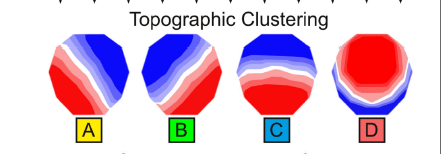

Per finire l’esposizione dei risultati ottenuti, si riportano i valori dei parametri temporali in Tabella 1. 

I risultati esposti ci hanno permesso di individuare il numero di microstati che descrivono al meglio il segnale, di visualizzarne la distribuzione spaziale e di studiarne la variazione nel tempo attraverso i parametri già descritti in precedenza.

### Bibliografia

- Berger H. Über das Elektrenkephalogramm des Menschen. Archiv f Psychiatrie. 1929; 87:527–570.

- Goldberger AL, Amaral LAN, Glass L, Hausdorff JM, Ivanov PCh, Mark RG, Mietus JE, Moody GB, Peng C-K, Stanley HE. PhysioBank, PhysioToolkit, and PhysioNet: Components of a New Research Resource for Complex Physiologic Signals. *Circulation* **101**(23):e215-e220 [Circulation Electronic Pages; [http://circ.ahajournals.org/cgi/content/full/101/23/e215](http://circ.ahajournals.org/cgi/content/full/101/23/e215)]; 2000 (June 13).

- Jung, T.-P., Makeig, S., Humphries, C., Lee, T., McKeown, M. J., Iragui, I., et al. (2000). Removing electroencephalographic aretfacts by blind source seperation. *Psychophysiology* 37, 163–178. doi: 10.1111/1469-8986.3720163

- Khanna, A., Pascual-Leone, A., Michel, C. M., and Farzan, F. (2015). Microstates in resting-state EEG: current status and future directions. *Neurosci. Biobehav. Rev.* 49, 105–113. doi: 10.1016/j.neubiorev.2014.12.010

- Koenig T, Prichep L, Lehmann D, Sosa PV, Braeker E, Kleinlogel H, Isenhart R, John ER. Millisecond by Millisecond, Year by Year: Normative EEG Microstates and Developmental Stages. NeuroImage. 2002; 16:41–48. [PubMed: 11969316]

- Lehmann, D., Ozaki, H., and Pal, I. (1987). EEG alpha map series: brain micro-states by space-oriented adaptive segmentation. *Electroencephalogr. Clin. Neurophysiol.* 67, 271–288. doi: 10.1016/0013-4694(87)90025-3

- Makeig, S., Bell, J., Jung, T.-P., and Sejnowski, T. J. (1996). Independent component analysis of electroencephalographic data. *Adv. Neural Inf. Process. Syst.* 8, 145–151. doi: 10.1109/ICOSP.2002.1180091

- Pascual-Marqui, R. D., Michel, C. M., and Lehmann, D. (1995). Segmentation of brain electrical activity into microstates: model estimation and validation. *Biomed. Eng. IEEE Trans.* 42, 658–665. doi: 10.1109/10.391164

- Schalk, G., McFarland, D.J., Hinterberger, T., Birbaumer, N., Wolpaw, J.R. [BCI2000: A General-Purpose Brain-Computer Interface (BCI) System.](http://www.ncbi.nlm.nih.gov/pubmed/15188875) *IEEE Transactions on Biomedical Engineering* **51**(6):1034-1043, 2004. 